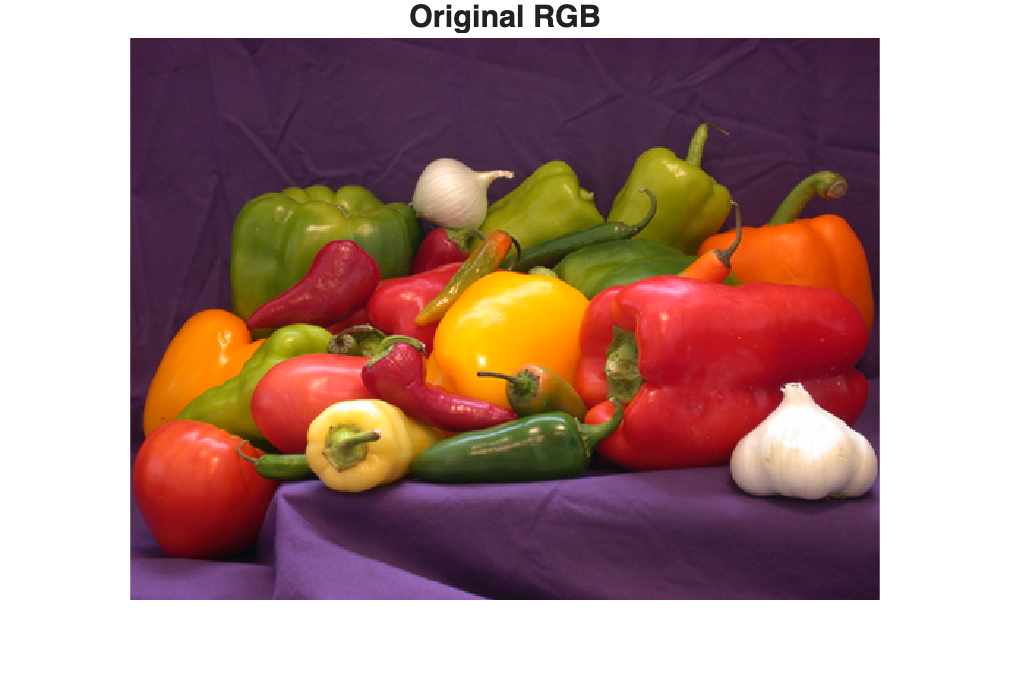

%% Lab 1: Image as a 2D Signal (Sampling, Quantization, Histograms, Enhancement)
%
% -------------------------------------------------------------------------
% Quick Notes:
% - If 'peppers.png' is not available, use 'cameraman.tif' or any local image.
% - Emphasize mapping: quantization→bit-depth; dynamic range→contrast; sampling→resize.
% - Gamma is nonlinear; contrast stretching is linear remapping.
% -------------------------------------------------------------------------
% HOW TO SUBMIT: include screenshots and short explanations for each section in GitHub. Submit only the GitHub URL.

close all; clear; clc;

%% 0) Load and inspect an image
if exist('peppers.png','file')
    I_rgb = imread('peppers.png');
else
    I_rgb = repmat(imread('cameraman.tif'),1,1,3); % fallback
end
figure; imshow(I_rgb); title('Original RGB');

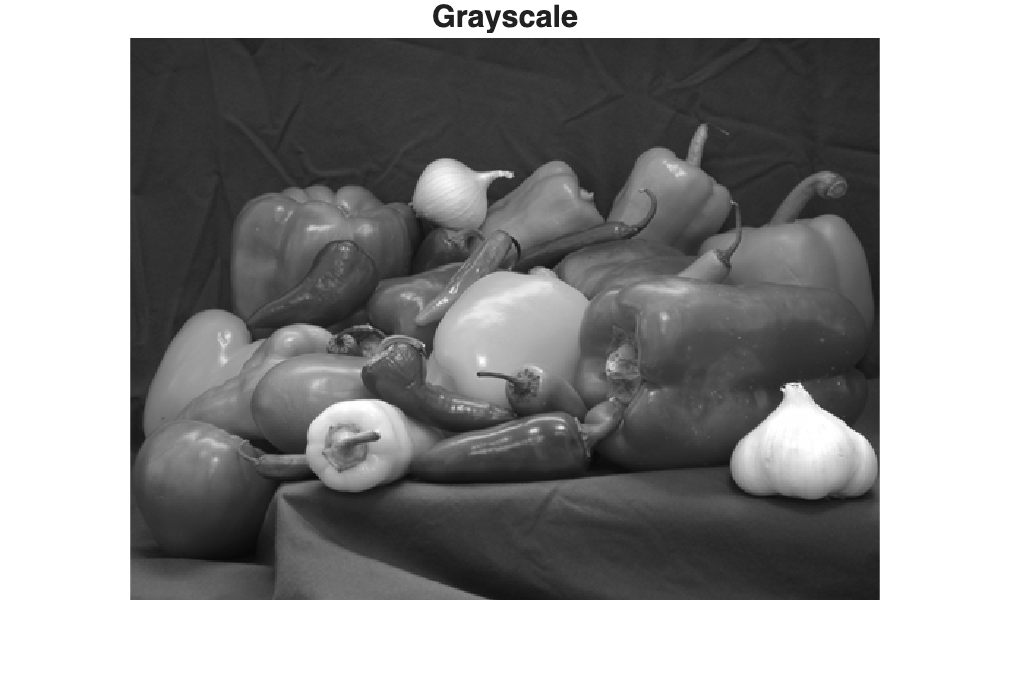


% Convert to grayscale (luminance)
if size(I_rgb,3)==3
    I = rgb2gray(I_rgb);
else
    I = I_rgb;
end
figure; imshow(I); title('Grayscale');


% Basic info
fprintf('Class: %s | Range: [%g, %g] | Size: %d x %d\n', ...
    class(I), double(min(I(:))), double(max(I(:))), size(I,1), size(I,2));

Class: uint8 | Range: [8, 255] | Size: 384 x 512


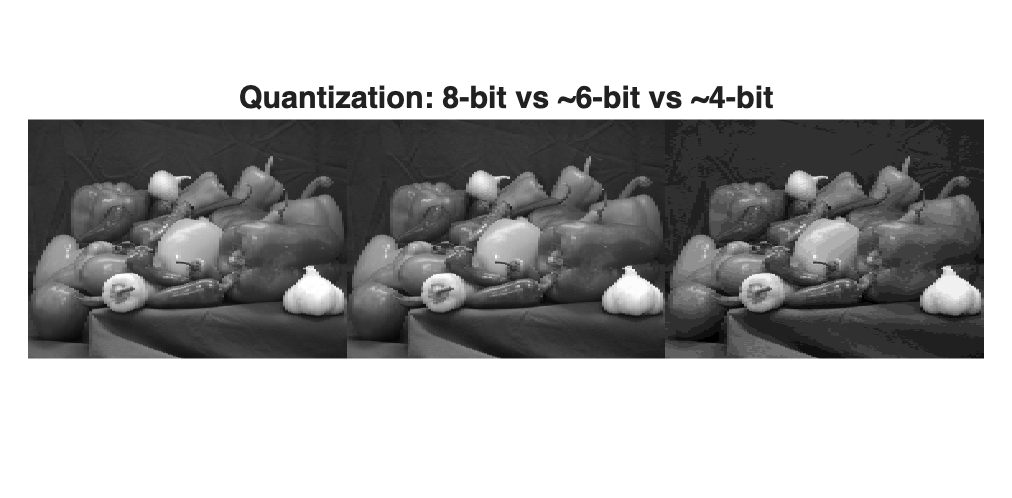


%% 1) Quantization and dynamic range
I8 = I; % 8-bit (0..255)
I6 = uint8(floor(double(I)/4)*4);   % ~6 bits (step size 4)
I4 = uint8(floor(double(I)/16)*16); % ~4 bits (step size 16)
figure; montage({I8,I6,I4},'Size',[1 3]);
title('Quantization: 8-bit vs ~6-bit vs ~4-bit');

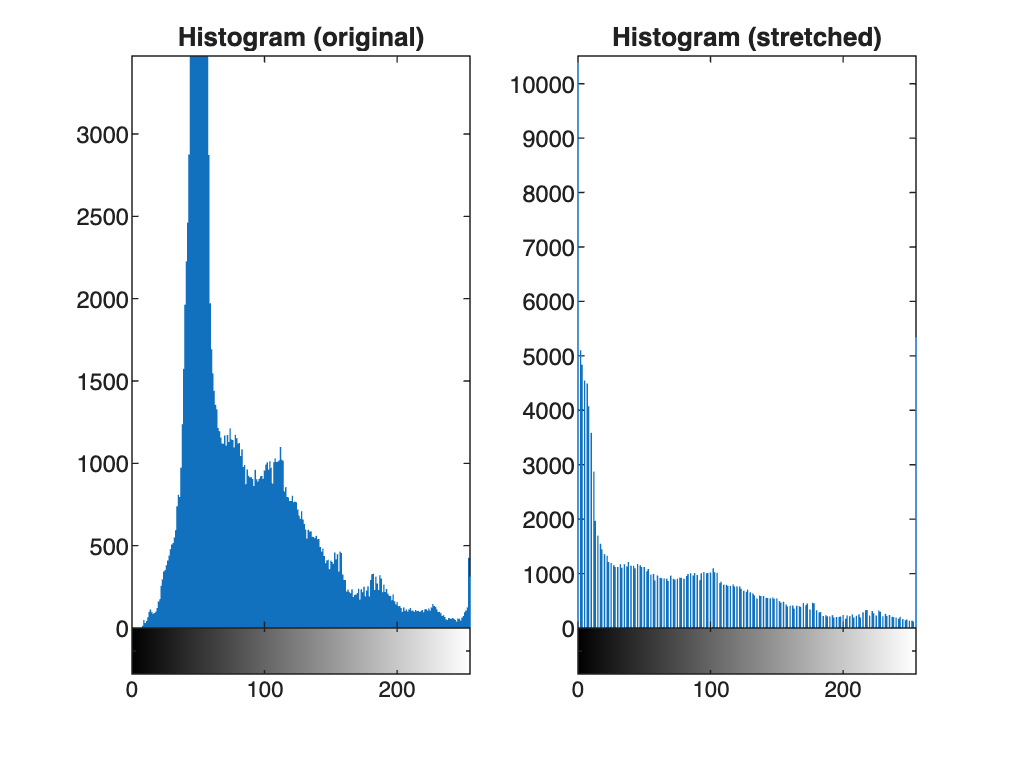


%% 2) Histogram and contrast stretching
figure;
subplot(1,2,1); imhist(I); title('Histogram (original)');

I_norm = mat2gray(I); % scales to [0,1]
I_stretch = imadjust(I,[0.2 0.8],[0 1]); % stretch mid-range

subplot(1,2,2); imhist(I_stretch); title('Histogram (stretched)');

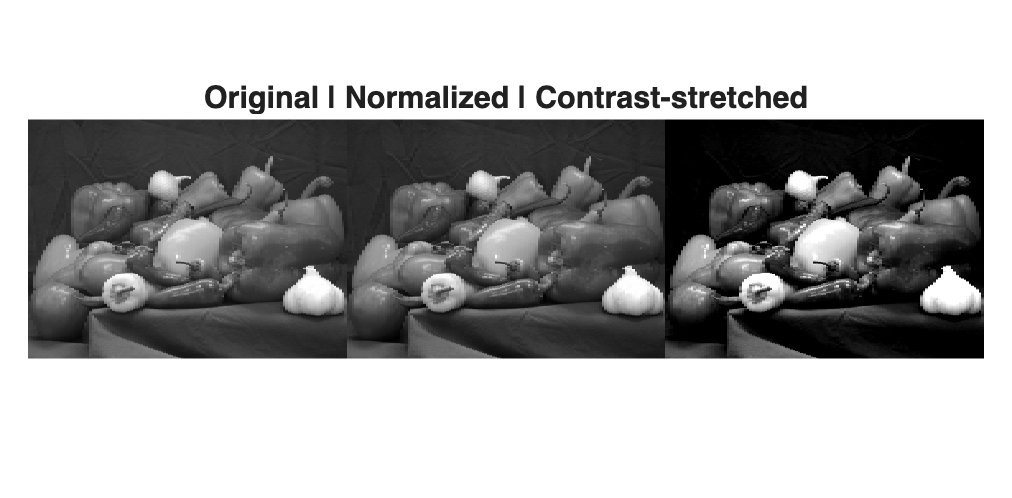


figure; montage({I, im2uint8(I_norm), im2uint8(I_stretch)},'Size',[1 3]);
title('Original | Normalized | Contrast-stretched');

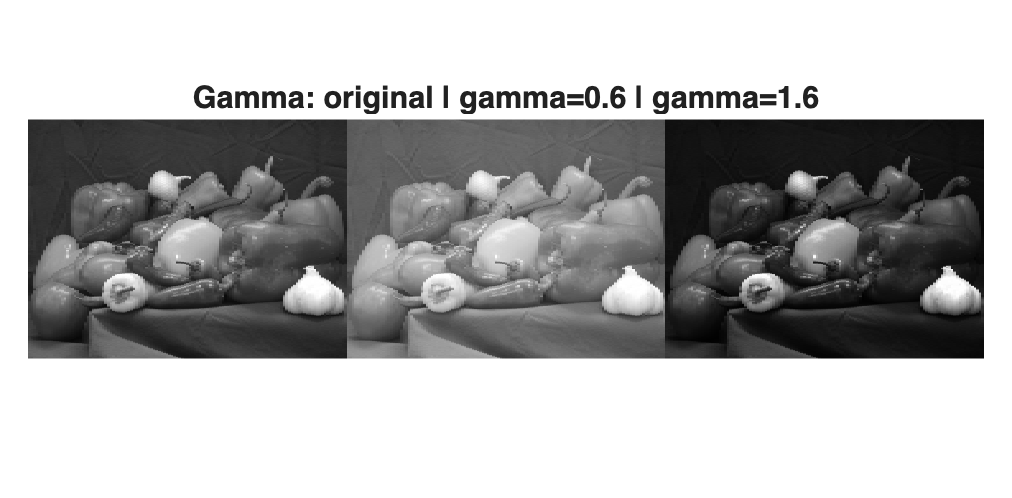


%% 3) Gamma correction (nonlinear amplitude scaling)
I_gamma_low = imadjust(I,[],[],0.6); % gamma < 1 brightens
I_gamma_high = imadjust(I,[],[],1.6); % gamma > 1 darkens
figure; montage({I,I_gamma_low,I_gamma_high},'Size',[1 3]);
title('Gamma: original | gamma=0.6 | gamma=1.6');

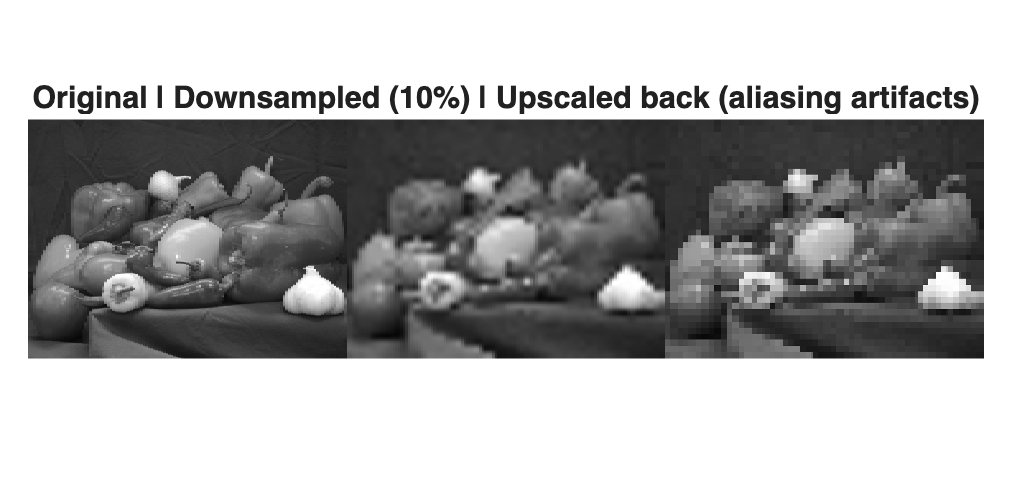


%% 4) Sampling and aliasing (downsample then upsample)
scale = 0.1; % 10% of original size
I_small = imresize(I, scale, 'nearest'); % naive downsampling
I_back = imresize(I_small, size(I), 'nearest');
figure; montage({I, I_small, I_back}, 'Size', [1 3]);
title('Original | Downsampled (10%) | Upscaled back (aliasing artifacts)');


%% 6) Short reflections (for your report)
% 1) Relate bit-depth to visible banding/posterization you observed.
% 2) How does contrast stretching change the histogram and visibility of details?
% 3) Explain why aggressive downsampling causes aliasing (reference Nyquist).
